clear
syms x y;
F(x,y)=x^2+2*x*y^2+3*y^4-6

$$F(x, y) = x^{2}+2\,x\,y^{2}+3\,y^{4}-6$$

M=[1 -1]

M =      1    -1


% Составить уравнение касательной и нормали к кривой F
% в точке M

ezplot(F)
hold on
plot(M(1),M(2),'ro')

DFx=diff(F,x)

$$DFx(x, y) = 2\,y^{2}+2\,x$$

pretty(DFx)

   2
2 y  + 2 x



DFy=diff(F,y)

$$DFy(x, y) = 12\,y^{3}+4\,x\,y$$

pretty(DFy)

    3
12 y  + 4 x y




Dyx=simplify(-diff(F,x)/diff(F,y))

$$Dyx(x, y) = -\frac{y^{2}+x}{6\,y^{3}+2\,x\,y}$$

pretty(Dyx)

      2
     y  + x
- ------------
     3
  6 y  + 2 x y




DyxM=subs(Dyx,[x y],M)

$$DyxM(x, y) = \frac{1}{4}$$

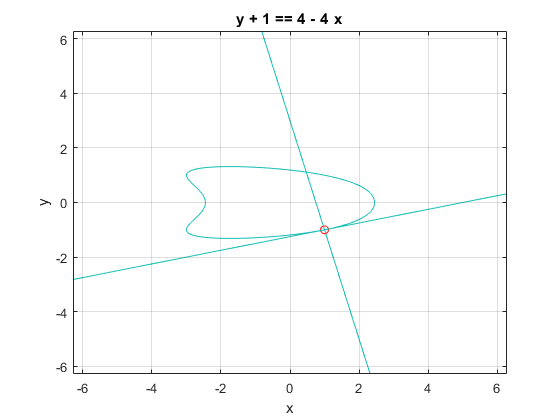


ezplot(y-M(2)==DyxM*(x-M(1)))
ezplot(y-M(2)==-1/DyxM*(x-M(1)))
grid
hold off